# Examples for using the `fmingrad` function.

Copyright © 2021 Tamas Kis

addpath(genpath('..'));

## Example #1: Local minimum of a simple function with a known gradient.

*Find the local minimizer of *$f\left(x,y\right)=x^2 +y^2$ near $\left(x_0 ,y_0 \right)=\left(10,10\right)\ldotp$

Defining $f\left(x,y\right)$,

fxy = @(x,y) x^2+y^2;

The `fmingrad` function can only accept a function handle that has a single aragument, so the solution is to rewrite $f\left(x,y\right)$ using the vector variable $\mathbf{x}={\left(x,y\right)}^T$. We do this in MATLAB by assigning a new function handle to $f\left(x,y\right)$.

f = @(x) fxy(x(1),x(2));

Alternatively, we can rewrite $f\left(x,y\right)=x^2 +y^2$ as $f\left(\mathbf{x}\right)=x_1^2 +x_2^2$ and directly define

f = @(x) x(1)^2+x(2)^2;

We also know the gradient of $f\left(\mathbf{x}\right)$ is

            
$$\nabla f\left(\mathbf{x}\right)=\left\lbrack \begin{array}{c}
2x_1 \\
2x_2 
\end{array}\right\rbrack$$


Defining the gradient in MATLAB as part of the `opts` structure,

opts.gradient = @(x) [2*x(1);
                      2*x(2)];

Next, defining the initial guess ${\mathbf{x}}_0 ={\left(x_0 ,y_0 \right)}^T ={\left(10,10\right)}^T$,

x0 = [10;
      10];

Finding the local minimizer using `fmingrad`,

x_min = fmingrad(f,x0,opts)

x_min = 	1.0e+-3 *

   0.597637441401356
   0.597637441401356


Instead of specifying the gradient in the `opts` structure, we can also just use the `fmingrad` function without specifying the gradient, in which case it resorts to using the complex-step approximation.

x_min = fmingrad(f,x0)

x_min = 	1.0e+-3 *

   0.597637441401356
   0.597637441401356


Note that we obtain the same exact result.

*Clearing variables from workspace so they do not conflict with subsequent examples,*

clear;

## Example #2: Speciying a constant learning rate.

*Repeat example #1 but using the constant learning rate* $\gamma \;=0\ldotp 001$.

Defining the objective function$f\left(\mathbf{x}\right)=x_1^2 +x_2^2$ and the initial guess ${\mathbf{x}}_0 ={\left(10,10\right)}^T$,

f = @(x) x(1)^2+x(2)^2;
x0 = [10;
      10];

Defining the gradient $\nabla f\left(\mathbf{x}\right)={\left(2x_1 ,2x_2 \right)}^T$ as part of the `opts` structure,

opts.gradient = @(x) [2*x(1);
                      2*x(2)];

Finding the local minimizer using `fmingrad` with a learning rate of $\alpha =0\ldotp 5$,

opts.alpha = 0.5;
x_min = fmingrad(f,x0,opts)

x_min = 	1.0e+-3 *

   0.597637441401356
   0.597637441401356


*Clearing variables from workspace so they do not conflict with subsequent examples,*

clear;

## Example #3: Plot of intermediate local minimum estimates.

*Find a local minimizer/minimum of *$f\left(\mathbf{x}\right)=100{\left(x_2 -x_1^2 \right)}^2 -{\left(1-x_1 \right)}^2$* using the gradient descent method with an initial guess of *${\mathbf{x}}_0 ={\left(-1\ldotp 5,-0\ldotp 5\right)}^T$* and using the complex-step approximation of a derivative. Additionally, produce a plot of the intermediate local minimum estimates obtained by the gradient descent method before it returned the converged local minimum.*

Defining $f\left(\mathbf{x}\right)$ and ${\mathbf{x}}_0$ in MATLAB,

f = @(x) 100*(x(2)-x(1)^2)^2+(1-x(1))^2;
x0 = [-1.5;-0.5];

To obtain the intermediate local minimizer and minimum estimates, we simply need to specify the `return_all` field of the `opts` structure as `true`.

opts.return_all = true;

Finding the local minimizer and minimum with `fmingrad`, using the complex-step approximation of a derivative,

[x_int,f_int] = fmingrad(f,x0,opts);

Since the local minimizer and local minimum are stored in the last elements of `x_int` and `f_int`, respectively,

x_min = x_int(:,end)

x_min =    0.796908973186212
   0.632900944328509


f_min = f_int(end)

f_min =    0.041713807890112


Thus, the local minimum is  $f_{\min } =f\left({\mathbf{x}}_{\min } \right)=0$ corresponding to the local minimizer of ${\mathbf{x}}_{\min } ={\left(1,1\right)}^T$. Next, calculating $f\left(\mathbf{x}\right)$ over the region $\left\lbrace \left(x_1 ,x_2 \right)\;|-2\le x_1 \le 5,\;-5\le x_2 \le 5\right\rbrace$ so we can plot it together with the intermediate local minimum estimates,

% defines region
x1 = -2:0.1:5;
x2 = -5:0.1:5;

% creates grid to represent region
[x1_grid,x2_grid] = meshgrid(x1,x2);

% evaluates f(x,y) over region
f_grid = 100*(x2_grid-x1_grid.^2).^2+(1-x1_grid).^2;

Plotting the intermediate local minimum estimates together with the function itself,

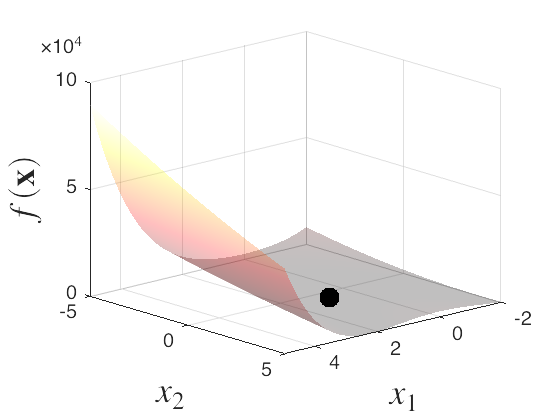

% initialize figure
figure;
hold on;

% function surface
s = surf(x1_grid,x2_grid,f_grid,'FaceAlpha',0.25);
colormap(hot);
shading interp;

% intermediate estimates of local minimum
plot3(x_int(1,:),x_int(2,:),f_int,'Color',[0.5490,0.0824,0.0824],'linewidth',1.5);

% converged local minimum
plot3(x_min(1),x_min(2),f_min,'k.','MarkerSize',30)

% plot formatting + labels
hold off;
grid on;
xlabel('$x_{1}$','Interpreter','latex','FontSize',18);
ylabel('$x_{2}$','Interpreter','latex','FontSize',18);
zlabel('$f(\mathbf{x})$','Interpreter','latex','FontSize',18);
view(138,20);

Looking at the plot, we can note that at one point, the estimates start divering rapidly. However, `fmingrad` recovers from this temporary divergence and ends up producing the correct local minimizer/minimum to within double precision.

Determining the number of iterations it took for the solution to converge (for comparison with the next example),

i_convergence = length(f_int)

i_convergence =      1


*Clearing variables from workspace so they do not conflict with subsequent examples,*

clear;

## Example #4: Maximization.

*Find the local maximum of the function *$g\left(\mathbf{x}\right)=100-{\left(x_1 -5\right)}^6 -{\left(x_2 -4\right)}^4$.

We are given the unconstrained optimization problem 

            
$$\underset{\mathbf{x}}{\textrm{maximize}} \;\;\;\;\;g\left(\mathbf{x}\right)$$


Equivalently, we can write

            
$$\underset{\mathbf{x}}{\textrm{minimize}} \;\;\;\;\;f\left(\mathbf{x}\right)$$


where $f\left(\mathbf{x}\right)=-g\left(\mathbf{x}\right)$ (which is the form we need to write the optimization problem in since the `fmingrad` function computes local *minima*). Defining $g\left(\mathbf{x}\right)$ and $f\left(\mathbf{x}\right)$ in MATLAB,

g = @(x) 100-(x(1)-5)^6-(x(2)-4)^4;
f = @(x) -g(x);

Solving for the local minimizer of $f\left(\mathbf{x}\right)$ using an initial guess of ${\mathbf{x}}_0 ={\left(0,0\right)}^T$,

x0 = zeros(2,1);
x_min = fmingrad(f,x0);

Let ${\mathbf{x}}_{\min }$ be the local *minimizer* of $f\left(\mathbf{x}\right)$, and ${\mathbf{x}}_{\max }$ be the local *maximizer* of $g\left(\mathbf{x}\right)$. The `fmingrad` function could also output `f_min`, which would be the local minimum, $f_{\min } =f\left({\mathbf{x}}_{\min } \right)$, of $f\left(\mathbf{x}\right)$. However, this would *not* be equal to the local maximum, $g_{\max } =g\left({\mathbf{x}}_{\max } \right)$, of $g\left(\mathbf{x}\right)$. However, since $f\left(\mathbf{x}\right)=-g\left(\mathbf{x}\right)$, the local minimizer of $f\left(\mathbf{x}\right)$ is the local maximizer of $g\left(\mathbf{x}\right)$.

            
$$x_{\min } =x_{\max }$$


x_max = x_min;

Calculating the local maximum of $g\left(\mathbf{x}\right)$ as $g\left({\mathbf{x}}_{\max } \right)$,

g_max = g(x_max)

g_max =   99.999999999998906


## Example #5: Speed test of "return all" vs. "fast" implementations.

*Repeat example #5 using both the "return all" and "fast" implementations and compare their speeds.*

Defining $f\left(\mathbf{x}\right)$ and ${\mathbf{x}}_0$ in MATLAB,

f = @(x) 100*(x(2)-x(1)^2)^2+(1-x(1))^2;
x0 = [-1.5;-0.5];

Specifying a learning rate scaling factor of $\alpha =0\ldotp 25$,

opts.lambda = 0.25;

Finding the local minimizer using `fmingrad` with the "return all" implementation and timing how long it takes,

tic
opts.return_all = true;
x_min = fmingrad(f,x0,opts);

return_all_time = toc

return_all_time =    0.011662427000000


Finding the local minimizer using `fmingrad` with the "fast" implementation and timing how long it takes,

tic
opts.return_all = false;
x_min = fmingrad(f,x0,opts);

fast_time = toc

fast_time =    0.008588864000000


*Clearing variables from workspace so they do not conflict with subsequent examples,*

clear;

## Example #6: Solution of a linear system.

*Solve the linear system *$\textrm{Ax}=\mathbf{b}$ for $\mathbf{x}$ where

            
$$\mathbf{A}=\left\lbrack \begin{array}{ccc}
2 & -1 & 5\\
1 & 1 & -2\\
2 & 4 & 1
\end{array}\right\rbrack ,\;\;\;\;\;\;\;\;\mathbf{b}=\left\lbrack \begin{array}{c}
10\\
-2\\
1
\end{array}\right\rbrack$$


Defining $\mathbf{A}$ and $\mathbf{b}$ in MATLAB,

A = [2,-1, 5;
     1, 1,-3;
     2, 4, 1];
b = [ 10;
     -2;
      1];

Since $\mathbf{A}$ is not positive definite, we use the objection function

            
$$f\left(\mathbf{x}\right)={\left\|\textrm{Ax}-\mathbf{b}\right\|}^2$$


which has the gradient

            
$$\nabla f\left(\mathbf{x}\right)=2{\mathbf{A}}^T \left(\textrm{Ax}-\mathbf{b}\right)$$


Defining $f\left(\mathbf{x}\right)$ and $\nabla f\left(\mathbf{x}\right)$ in MATLAB,

f = @(x) norm(A*x-b)^2;
opts.gradient = @(x) 2*A.'*(A*x-b);

Solving the linear system using the `fmingrad` function with an initial guess of ${\mathbf{x}}_0 ={\left(0,0,0\right)}^T$,

x0 = ones(3,1);
x = fmingrad(f,x0,opts)

x =    1.999781352284768
  -0.999923731848773
   0.999237939771435


Checking our result using MATLAB's linear solver,

 x = A\b

x =      2
    -1
     1


*Clearing variables from workspace so they do not conflict with subsequent examples,*

clear;

## Example #7: Solution of a nonlinear system.

*Solve the nonlinear system of equations*

            
$$3x_1 -\cos \left(x_2 x_3 \right)=\frac{3}{2}$$


            
$$4x_1^2 -625x_2^2 +2x_2 =1$$


            
$$\exp \left(-x_1 x_2 \right)+20x_3 =\frac{3-10\pi }{3}$$


*for *$\mathbf{x}=\left(x_1 ,x_2 ,x_3 \right)$*.*

First, let's rewrite the equations so their right hand side is 0.

            
$$3x_1 -\cos \left(x_2 x_3 \right)-\frac{3}{2}=0$$


            
$$4x_1^2 -625x_2^2 +2x_2 -1=0$$


            
$$\exp \left(-x_1 x_2 \right)+20x_3 +\frac{10\pi -3}{3}=0$$


Let's define the vector-valued function $\mathbf{g}\left(\mathbf{x}\right)$.

            
$$\mathbf{g}\left(\mathbf{x}\right)=\left\lbrack \begin{array}{c}
3x_1 -\cos \left(x_2 x_3 \right)-\frac{3}{2}\\
4x_1^2 -625x_2^2 +2x_2 -1\\
\exp \left(-x_1 x_2 \right)+20x_3 +\frac{10\pi -3}{3}
\end{array}\right\rbrack$$


Defining $\mathbf{g}\left(\mathbf{x}\right)$ in MATLAB,

g = @(x) [3*x(1)-cos(x(2)*x(3))-(3/2);
          4*x(1)^2-625*x(2)^2+2*x(2)-1;
          exp(-x(1)*x(2))+20*x(3)+((10*pi-3)/3)];

Therefore, we want to solve for $\mathbf{x}$ such that $\mathbf{g}\left(\mathbf{x}\right)={\left(0,0,0\right)}^T$. If $\mathbf{g}\left(\mathbf{x}\right)={\left(0,0,0\right)}^{T\;}$, then ${\left\|{\mathbf{g}\left(\mathbf{x}\right)}^T \mathbf{g}\left(\mathbf{x}\right)\right\|}^2 ={\mathbf{g}\left(\mathbf{x}\right)}^T \mathbf{g}\left(\mathbf{x}\right)=0$. Since ${\mathbf{g}\left(\mathbf{x}\right)}^T \mathbf{g}\left(\mathbf{x}\right)>0\;\forall \;\mathbf{x}$, we choose our objective function, $f\left(\mathbf{x}\right)$, to be

            
$$f\left(\mathbf{x}\right)={\mathbf{g}\left(\mathbf{x}\right)}^T \mathbf{g}\left(\mathbf{x}\right)$$


Defining $f\left(\mathbf{x}\right)$ in MATLAB,

f = @(x) g(x).'*g(x);

Note that we must take care to use the non-conjugate transpose (`.'`) instead of the conjugate tranpose (`'`) since by default, the `fmingrad` function uses the complex-step approximation of the derivative, and using the conjugate transpose would pose some problems for that approximation (see Section 1.4 of [https://tamaskis.github.io/documentation/Numerical_Differentiation_using_the_Complex_Step_Approximation.pdf](https://tamaskis.github.io/documentation/Numerical_Differentiation_using_the_Complex_Step_Approximation.pdf)). Solving for $\mathbf{x}$ using the `fmingrad` function,

x0 = zeros(3,1);
x = fmingrad(f,x0)

x =    0.741826326089557
   0.046107474300997
  -0.521958504911318


Verifying that this solution for $\mathbf{x}$ results in $\mathbf{g}\left(\mathbf{x}\right)={\left(0,0,0\right)}^T$,

g(x)

ans =   -0.274231444997306
  -0.035246850590582
  -0.000819989165691


*Clearing variables from workspace so they do not conflict with subsequent examples,*

clear;

## Example #8: Constrained Optimization

*Consider the following constrained optimization problem:*

            
$$\underset{\mathbf{x}}{\textrm{minimize}} \;\;\;\;\;x_1^2 +x_2^2$$


            
$$\textrm{subject}\;\textrm{to}$$
    
$$x_1 \ge \;2$$


                               
$$x_2 \le -2$$


*Solve this optimization problem using the gradient descent method.*

First, we note that we are given two inequality constraints. First, let's rewrite them as

            
$$-x_1 +2\le 0$$


            
$$x_2 +2\le 0$$


We can combine them as a single vector-valued inequality constraint:

            
$$\left\lbrack \begin{array}{c}
-x_1 +2\\
x_2 +2
\end{array}\right\rbrack \le \left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\to \;\;\;\;\;\;\;\;\;\;\mathbf{g}\left(\mathbf{x}\right)=\left\lbrack \begin{array}{c}
-x_1 +2\\
x_2 +2
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\to \;\;\;\;\;\;\;\;\;\;\mathbf{g}\left(\mathbf{x}\right)\le 0$$


Additionally, let's define the objective function for the constrained problem.

            
$$f_c \left(\mathbf{x}\right)=x_1^2 +x_2^2$$


Defining the objective function for the constrained problem in MATLAB,

fc = @(x) x(1)^2+x(2)^2;

We can now write our constrained optimization problem in standard form as

            
$$\underset{\mathbf{x}}{\textrm{minimize}} \;\;\;\;\;f_c \left(\mathbf{x}\right)$$


            
$$\textrm{subject}\;\textrm{to}$$
   
$$\mathbf{g}\left(\mathbf{x}\right)\le 0$$


We can convert this to the unconstrained optimization problem

            
$$\underset{\mathbf{x}}{\textrm{minimize}} \;\;\;\;\;f\left(\mathbf{x}\right)$$


 by defining the objective function as

            
$$f\left(\mathbf{x}\right)=f_c \left(\mathbf{x}\right)+p_g \left(\mathbf{x}\right)$$


where $p_g \left(\mathbf{x}\right)$ is defined piecewise as

            
$$p_g \left(\mathbf{x}\right)=\left\lbrace \begin{array}{ll}
0 & \mathbf{g}\left(\mathbf{x}\right)\le 0\\
w_g {\left\|\mathbf{g}\left(\mathbf{x}\right)\right\|}^2  & \mathbf{g}\left(\mathbf{x}\right)>0
\end{array}\right.$$


Since the penalty function $p_g \left(\mathbf{x}\right)$ is defined piecewise, it requires an `if`/`else` structure to define it in a computational setting. Therefore, we must define it as a MATLAB function and then assign it a function handle. MATLAB function definitions must be done at the end of the script, so see the **"Penalty Function for Example #10"** section at the bottom of this page. Also note that the penalty function requires $\mathbf{g}\left(\mathbf{x}\right)$ for evaluation. Therefore, we first define $\mathbf{g}\left(\mathbf{x}\right)$ in MATLAB.

g = @(x) [-x(1)+2;
          x(2)+2];

In this case, we use the weight $w_g ={10}^5$. Using a heavier weight would result in a more accurate solution, but would also increase the computational time.

wg = 1e5;

Assigning the function handle to the penalty function,

pg = @(x) inequality_penalty(g,x,wg);

Defining the objective function for the unconstrained problem,

f = @(x) fc(x)+pg(x);

Solving the optimization problem using the `fmingrad` function with an initial guess of ${\mathbf{x}}_0 ={\left(5,-5\right)}^T$,

x0 = [ 5;
      -5];
[x_min,f_min] = fmingrad(f,x0)

x_min =    2.000419575725626
  -2.000419575725626


f_min =    8.003356957892588


Thus, the solution to the optimization problem is  $f_{\min } =f\left({\mathbf{x}}_{\min } \right)=8$ corresponding to the local minimizer of ${\mathbf{x}}_{\min } ={\left(2,-2\right)}^T$. Next, calculating $f\left(\mathbf{x}\right)$ over the region $\left\lbrace \left(x_1 ,x_2 \right)\;|2\le x_1 \le 6,\;-6\le x_2 \le -2\right\rbrace$ (note that this corresponds to a subset of the constrained region for $\mathbf{x}$ )so we can plot the local minimum in the constrained region,

% defines region
x1 = 2:0.1:6;
x2 = -6:0.1:-2;

% creates grid to represent region
[x1_grid,x2_grid] = meshgrid(x1,x2);

% evaluates f(x) over region
f_grid = x1_grid.^2+x2_grid.^2;

Plotting the function and the minimum over the constrained region

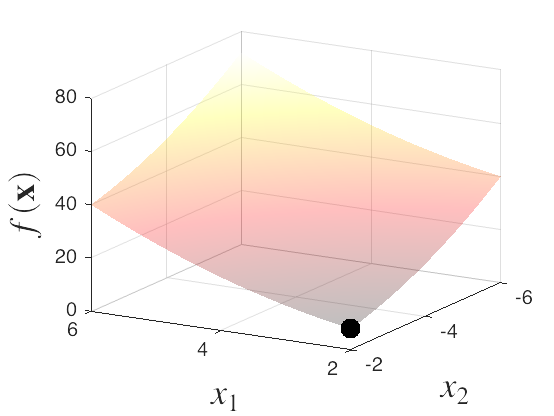

% initialize figure
figure;
hold on;

% function surface
s = surf(x1_grid,x2_grid,f_grid,'FaceAlpha',0.25);
colormap(hot);
shading interp;

% converged local minimum
plot3(x_min(1),x_min(2),f_min,'k.','MarkerSize',30)

% plot formatting + labels
hold off;
grid on;
xlabel('$x_{1}$','Interpreter','latex','FontSize',18);
ylabel('$x_{2}$','Interpreter','latex','FontSize',18);
zlabel('$f(\mathbf{x})$','Interpreter','latex','FontSize',18);
view(210,20);

## **Penalty Function for Example #10**

The penalty function for an arbitrary inequality constraint is defined as

            
$$p_g \left(\mathbf{x}\right)=\left\lbrace \begin{array}{ll}
0 & \mathbf{g}\left(\mathbf{x}\right)\le 0\\
w_g {\left\|\mathbf{g}\left(\mathbf{x}\right)\right\|}^2  & \mathbf{g}\left(\mathbf{x}\right)>0
\end{array}\right.$$


Note that in MATLAB, we need to define the 2-norm using the `inorm` function from the [*Numerical Differentiation Toolbox*](https://www.mathworks.com/matlabcentral/fileexchange/97267-numerical-differentiation-toolbox) (this complexified version of the `norm` function is required for the correct evaluation of the 2-norm's gradient using the complex-step approximation).

function pg = inequality_penalty(g,x,wg)

    % evaluate g(x)
    gx = g(x);

    % determines penalty
    if gx <= 0
        pg = 0;
    else
        pg = wg*inorm(gx)^2;
    end

end